# 4.9 Discrete controller and observer

% select the sampling time
fSamplingPeriod = 0.005;

load poles.mat
load Linear_Param.mat
poles

poles = 1.0e+02 *

 -6.647578321185790 + 0.000000000000000i
 -0.050809320558218 + 0.000000000000000i
 -0.024802368383212 + 0.003520540040557i
 -0.024802368383212 - 0.003520540040557i


A;
B = B(:,1);
C = [1 0 0 0;
    0 0 1 0];
D = 0;
contStateSpace = ss(A,B,C,D)

contStateSpace =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0    -435  -6.099   9.136
   x3       0       0       0       1
   x4       0    1903   62.02  -39.97
 
  B = 
           u1
   x1       0
   x2   20.58
   x3       0
   x4  -90.03
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



discreteStateSpace = c2d(contStateSpace,fSamplingPeriod);
Ad = discreteStateSpace.A

Ad =    1.000000000000000   0.002169375804939  -0.000035615030253   0.000059371727425
                   0   0.169257508881752  -0.009548994253862   0.017409977283237
                   0   0.012386212728786   1.000597546217141   0.004740938014341
                   0   3.635660710145991   0.218485145882911   0.924248671303915


Bd = discreteStateSpace.B

Bd =    0.000133880874091
   0.039291874579947
  -0.000585834385821
  -0.171956925479762


Cd = discreteStateSpace.C

Cd =      1     0     0     0
     0     0     1     0


D = discreteStateSpace.D

D =      0
     0


discretePoles = exp(poles*fSamplingPeriod)

discretePoles =   0.036016102077587 + 0.000000000000000i
  0.974915322689814 + 0.000000000000000i
  0.987673863433712 + 0.001738574487302i
  0.987673863433712 - 0.001738574487302i



%Plotting discrete poles
scatter(real(discretePoles),imag(discretePoles))
hold on
r = 1

r =      1


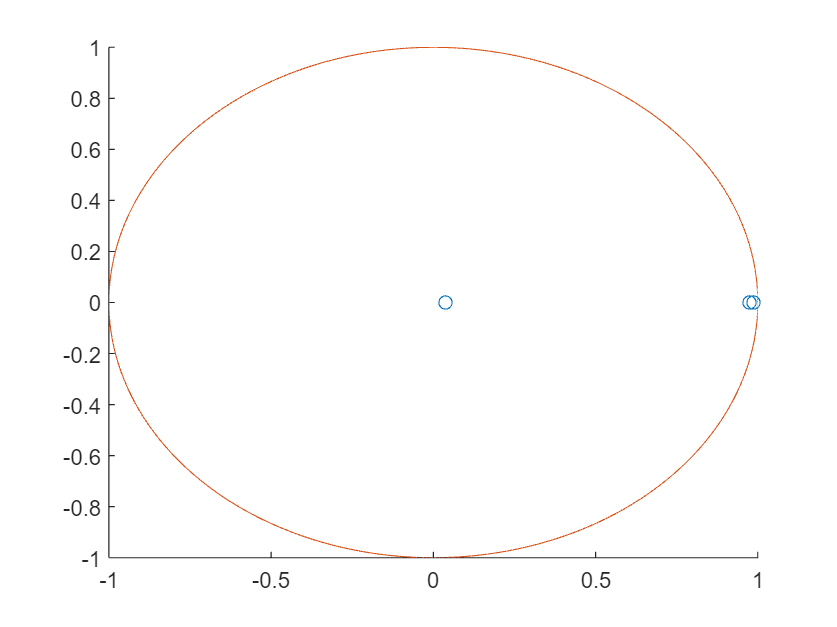

ang=0:0.01:2*pi; 
xp=r*cos(ang);
yp=r*sin(ang);
plot(xp,yp);
hold off

Controller

%State-feedback gain
Kd = place(Ad,Bd,discretePoles)

Kd =  -21.591087336334571 -42.551783932189117 -61.688402044360444 -10.156702754675313


vpa(sym(Kd),5)

$$ans = \left(\begin{array}{cccc} -21.591 & -42.552 & -61.688 & -10.157 \end{array}\right)$$

eig(Ad-Bd*Kd)

ans =   0.036016102077588 + 0.000000000000000i
  0.974915322689812 + 0.000000000000000i
  0.987673863433714 + 0.001738574487320i
  0.987673863433714 - 0.001738574487320i


Full-state observer

factor = 4;
speed = max(abs(poles(2:4)));
contObserverPoles(1) = poles(1);
contObserverPoles(2) = -2*factor*speed; % Place pole to not disturb dominant poles
omegan = factor*speed;
zeta = 0.99;
contObserverPoles(3:4) =    [omegan*(-zeta+1i*sqrt(1-zeta^2));
                             omegan*(-zeta-1i*sqrt(1-zeta^2))];
desiredPoles = exp(contObserverPoles*fSamplingPeriod)

desiredPoles =   0.036016102077587 + 0.000000000000000i  0.816084576079421 + 0.000000000000000i  0.904199546753915 + 0.012962654808095i  0.904199546753915 - 0.012962654808095i


Ld = (place(Ad',Cd',desiredPoles))'

Ld =    0.113484873259293   0.005230485803754
  -1.368187222013990   4.373246417429888
   0.023678681424714   0.320119081478682
   6.390941774774537 -15.265502826389531


vpa(sym(Ld),5)

$$ans = \left(\begin{array}{cc} 0.11348 & 0.0052305\\ -1.3682 & 4.3732\\ 0.023679 & 0.32012\\ 6.3909 & -15.266 \end{array}\right)$$

eig(Ad-Ld*Cd)

ans =   0.036016102077587 + 0.000000000000000i
  0.816084576079418 + 0.000000000000000i
  0.904199546753914 + 0.012962654808093i
  0.904199546753914 - 0.012962654808093i


Reduced order observer

T = inv([C;0 1 0 0; 0 0 0 1])

T =      1     0     0     0
     0     0     1     0
     0     1     0     0
     0     0     0     1


An = inv(T)*Ad*T ;  %New A-matrix
Bn = inv(T)*Bd;     %New B-matrix
Cbacc = Cd(1,:)*T;  %Accurate
Cbnacc = Cd(2,:)*T; %Not accurate

Ayy = An(1,1); %Zero
Ayx = An(1,2:4);  %Noisy/unobserved states
Axy = An(2:4,1); % Zero
Axx = An(2:4,2:4); %Noisy/unobserved states

By = Bn(1);
Bx = Bn(2:4);

Cy = Cbnacc(1);
Cx = Cbnacc(2:4);

AA = Axx;
CC = [Ayx
      Cx];
Lpartial = ( place( AA', CC', desiredPoles(2:4) ) )';
Lacc = Lpartial(:,1);
Lnacc = Lpartial(:,2);

poles(2:4);
observerPoles = eig(AA-Lpartial*CC)

observerPoles =   0.816084576079422 + 0.000000000000000i
  0.904199546753916 + 0.012962654808095i
  0.904199546753916 - 0.012962654808095i



M1d = Axx-Lacc*Ayx-Lnacc*Cx

M1d =    0.818659998491391   0.020545832728813   0.004964251436306
   0.021296637071723   0.986017031864519   0.039763146180775
  -0.022468517782344  -0.180533078124422   0.819806639231342


vpa(sym(M1d),5)

$$ans = \left(\begin{array}{ccc} 0.81866 & 0.020546 & 0.0049643\\ 0.021297 & 0.98602 & 0.039763\\ -0.022469 & -0.18053 & 0.81981 \end{array}\right)$$

M2d = Bx-Lacc*By

M2d =   -0.000082271538219
   0.089697377679051
  -0.407469536485466


vpa(sym(M2d),5)

$$ans = \left(\begin{array}{c} -0.000082272\\ 0.089697\\ -0.40747 \end{array}\right)$$

M3d = Axy-Lacc*Ayy-Lnacc*Cy

M3d = 1.0e+03 *

   0.003761275469862
   0.376495174844035
  -1.759120655620328


vpa(sym(M3d),5)

$$ans = \left(\begin{array}{c} 3.7613\\ 376.5\\ -1759.1 \end{array}\right)$$

M4d = Lnacc

M4d =    0.181803589786101
  -0.044254518367789
   0.303604799033966


vpa(sym(M4d),5)

$$ans = \left(\begin{array}{c} 0.1818\\ -0.044255\\ 0.3036 \end{array}\right)$$

M5d = Lacc

M5d = 1.0e+03 *

  -0.003761275469862
  -0.376495174844035
   1.759120655620328


vpa(sym(M5d),5)

$$ans = \left(\begin{array}{c} -3.7613\\ -376.5\\ 1759.1 \end{array}\right)$$

M6d = T(:,1)

M6d =      1
     0
     0
     0


vpa(sym(M6d),5)

$$ans = \left(\begin{array}{c} 1.0\\ 0\\ 0\\ 0 \end{array}\right)$$

M7d = T(:,2:4)

M7d =      0     0     0
     0     1     0
     1     0     0
     0     0     1


vpa(sym(M7d),5)

$$ans = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 1.0 & 0\\ 1.0 & 0 & 0\\ 0 & 0 & 1.0 \end{array}\right)$$

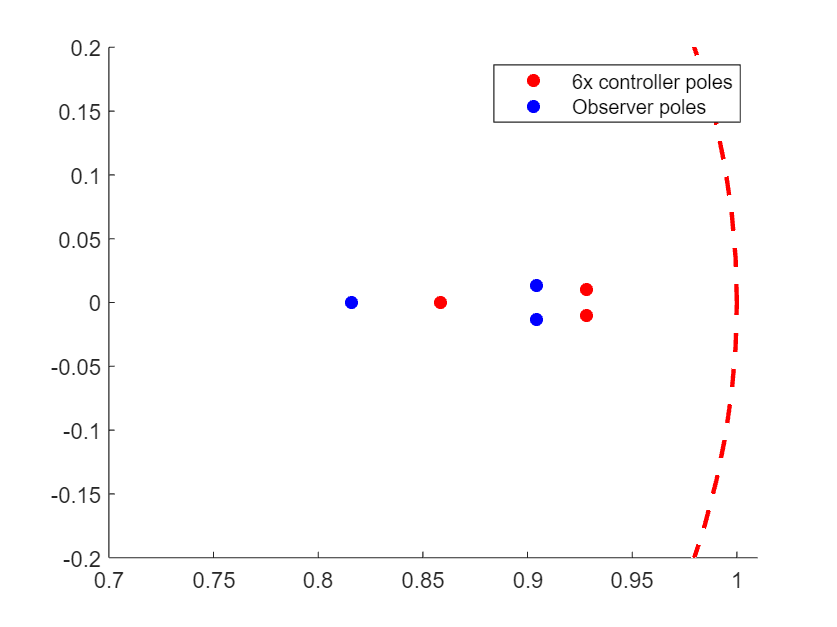



scatter(real(discretePoles.^6),imag(discretePoles.^6),"red","filled")
hold on
scatter(real(desiredPoles),imag(desiredPoles),"blue","filled")
viscircles([0 0], 1,'LineStyle','--');
hold off
legend("6x controller poles","Observer poles")
xlim([0.7 1.01])
ylim([-0.2 0.2])